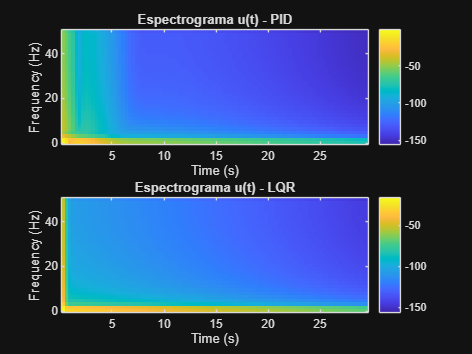

% espectrograma_comparativo_base.m
% G1 - Controle de Altitude de Drone
% Responsavel: Kauã
% Objetivo: gerar o espectrograma comparativo PID vs LQR quando o vetor u_lqr estiver disponivel.

%clear; clc; close all;

load('dados_pid.mat'); % deve conter t e u do PID
u_pid = u(:);
t = t(:);
dt = mean(diff(t));
fs = 1/dt;

% Quando Rafael enviar o LQR, salvar um arquivo dados_lqr.mat contendo u_lqr
% e use o mesmo vetor de tempo t.
if isfile('dados_lqr.mat')
    load('dados_lqr.mat');
    u_lqr = u_lqr(:);

    figure;
    subplot(2,1,1);
    spectrogram(u_pid, 64, 32, 64, fs, 'yaxis');
    title('Espectrograma u(t) - PID');
    colorbar;

    subplot(2,1,2);
    spectrogram(u_lqr, 64, 32, 64, fs, 'yaxis');
    title('Espectrograma u(t) - LQR');
    colorbar;

    exportgraphics(gcf, 'fig_espectrograma_comparativo.png', 'Resolution', 600);
else
    figure;
    spectrogram(u_pid, 64, 32, 64, fs, 'yaxis');
    title('Espectrograma u(t) - PID (preliminar; aguardando u_lqr)');
    colorbar;
    exportgraphics(gcf, 'fig_espectrograma_pid_preliminar.png', 'Resolution', 600);
end